function [x,v,H] = Simulation(x_0, v_0, m, sigma, k_inter, k_center, t_max, dt)
%{
TAKES initial condition vectors x_0, v_0; sim params t_max, dt:

    Vector x_0:
    (
    (x1,x2,x3)1,
    (x1,x2,x3)2,
    ...
    (x1,x2,x3)N
    ),

    Vector v_0:
    (
    (v1,v2,v3)1,
    (v1,v2,v3)2,
    ...
    (v1,v2,v3)N
    )

    Vector m (Nx1): 
    ()
    Scalar time cutoff t_max, step size dt.

RETURNS tensor of:
  positions vs. time
  velocities vs. time
  and E vs. time

    tensor x: (t,N,3)
    (
    (x1,x2,x3)1t1, (x1,x2,x3)1t2,...(x1,x2,x3)1t_max,
    (x1,x2,x3)2t1, (x1,x2,x3)2t2,...(x1,x2,x3)2t_max,
    ...
    (x1,x2,x3)Nt1, (x1,x2,x3)Nt2,...(x1,x2,x3)Nt1_max,
    ),
    tensor v: (t,N,3)
    Same thing
    list E (t)
%}
    if size(x_0, 1) == 1
        x_0 = squeeze(x_0);
        v_0 = squeeze(v_0);
    end
    N = size(x_0, 1);
    num_t_steps = cast(t_max / dt, 'uint64'); % round to correct timesteps
    
    % t_max_round = dt * num_t_steps; % round to correct timesteps

    x = zeros(num_t_steps + 1, N, 3);
    v = zeros(num_t_steps + 1, N, 3);
    m_reshaped = reshape(m, [1, numel(m), 1]);
    
    % Set initial conditions
    x(1,:,:) = x_0;
    v(1,:,:) = v_0;
    
    H = zeros(num_t_steps + 1, 1);
    H(1) = calculate_energy(squeeze(x(1,:,:)), squeeze(v(1,:,:)), m, sigma, k_inter, k_center);
    
    for step = 1:num_t_steps % next step is at step + 1; loop doesn't go there
        x_now = x(step,:,:);
        v_now = v(step,:,:);
        F_now = calculate_force(x_now, sigma, k_inter, k_center);

        x_next = x_now + v_now * dt + (F_now./(2*m_reshaped) * dt^2);
        F_next = calculate_force(x_next, sigma, k_inter, k_center);

        v_next = v_now + ((dt* (F_now + F_next)./(2*m_reshaped)));

        x(step + 1,:,:) = x_next;
        v(step + 1,:,:) = v_next;
        H(step + 1) = calculate_energy(squeeze(x_next), squeeze(v_next), m, sigma, k_inter, k_center);
    end

end

function F = calculate_force(x_t, sigma, k_inter, k_center)
% takes a vector of particle states at a given time t.
% takes vectors of diameters
% assume center is 0 0 0
% returns an Nx3 vector of forces
    N = size(x_t,1);
    x_center = zeros(N,3);
    
    % CENTRAL FORCE
    F = k_center * (x_center - x_t);

    % INTERACTION FORCES
    for i = 1:(N-1)
        for j = (i+1):N
            distance = norm(x_t(i,:)-x_t(j,:));

            F(i,:) = F(i,:)...
                + k_inter * Heaviside((sigma(i) + sigma(j))/2 - distance) * (x_t(i,:) - x_t(j,:))...
                * (((sigma(i)+sigma(j))/(2 * distance))-1); % j on i
            F(j,:) = F(j,:)...
                + k_inter * Heaviside((sigma(j) + sigma(i))/2 - distance) * (x_t(j,:) - x_t(i,:))...
                * (((sigma(i)+sigma(j))/(2 * distance))-1); % i on j
        end
    end
end 

function S = Heaviside(x)
% Implementation of the Heaviside Step Function
    if ~isscalar(x)
        error('input is not a scalar')
    end
    if x < 0
        S = 0;
    else
        S = 1;
    end
end

function H = calculate_energy(x_t, v_t, m, sigma, k_inter, k_center)
% assume center is 0 0 0
% returns scalar energy value
    N = size(x_t, 1);
    x_center = zeros(N,3);
    
    T = (1/2) * sum(sum(m .* (v_t.^2)));

    V_center = sum(0.5*k_center*vecnorm(x_t - x_center, 2 , 2).^2);

    V_inter = 0;
    for i = 1:(N-1)
        for j = (i+1):N
            distance = norm(x_t(i,:) - x_t(j,:));
            overlap = max(0, (sigma(i) + sigma(j))/2 - distance);
            V_inter = V_inter + 0.5 * k_inter * overlap^2;
        end
    end
    H = T + V_center + V_inter;
end

% FULL SIM TEST CODE
total_time = 30;
N = 3;
sigma = rand(N,1);
k_inter = 1;
k_center = 0.1;
mass = rand(N,1);

x_0 = rand(N,3);
v_0 = rand(N,3);

% Range of dt values to test
dt_values = logspace(-5, -2, 40);
std_H = zeros(size(dt_values));
len = length(dt_values);

len = 40

% Run simulations for different dt values
for i = 1:length(dt_values)
    [x,v,H] = Simulation(x_0, v_0, mass, sigma, k_inter, k_center, total_time, dt_values(i));
    std_H(i) = std(H);
    disp(i + '/' + len)
end

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125

   126

   127




% Plot log-log
figure;
loglog(dt_values, std_H, 'o-');
xlabel('Time step (dt)');
ylabel('std(H)');
title('Energy Conservation: std(H) vs dt');

% Fit a line
p = polyfit(log(dt_values), log(std_H), 1);
disp(['Slope of log-log plot: ', num2str(p(1))]);

Slope of log-log plot: 2.0003


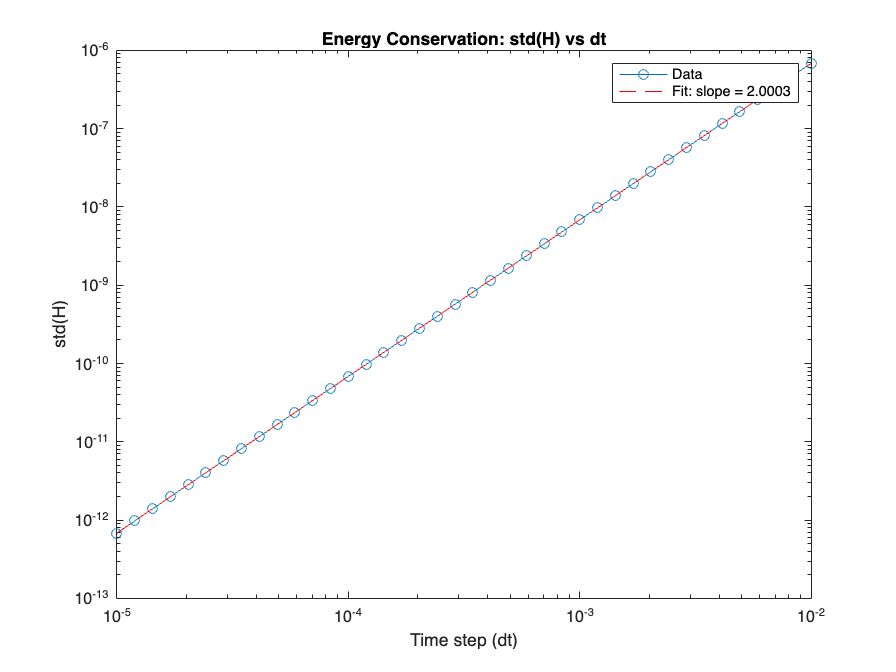


% Add fitted line to the plot
hold on;
loglog(dt_values, exp(p(2)) * dt_values.^p(1), 'r--');
legend('Data', ['Fit: slope = ' num2str(p(1))]);

%{
% FORCE CALCULATION TEST CODE
N = 3;  % Number of particles
x_t = [
    0, 0, 0;  % Particle 1 at origin
    1, 0, 0;  % Particle 2 on x-axis
    0, 1, 0   % Particle 3 on y-axis
];
sigma = [2; 2; 2];  % All particles have diameter 0.5
k_inter = 1.0;  % Interaction spring constant
k_center = 0.5;  % Center spring constant

F = calculate_force(x_t, sigma, k_inter, k_center);

% Display results
disp('Input positions (x_t):');
disp(x_t);
disp('Particle diameters (sigma):');
disp(sigma);
disp('Calculated forces (F):');
disp(F);

% Expected results (approximate due to floating-point arithmetic)
expected_F = [
    -1, -1, 0.0000;  % Force on particle 1
    k_inter - k_center + (k_inter * (2-sqrt(2))/sqrt(2)), (-1 * (2-sqrt(2))/sqrt(2)), 0.0000;  % Force on particle 2
    (-1 * k_inter * (2-sqrt(2))/sqrt(2)), k_inter - k_center + (k_inter * (2-sqrt(2))/sqrt(2)), 0.0000  % Force on particle 3
];

disp('Expected forces:');
disp(expected_F);

% Check if calculated forces are close to expected forces
tolerance = 1e-4;
if all(abs(F(:) - expected_F(:)) < tolerance)
    disp('Test passed within tolerance.');
else
    disp('Test failed.');
    disp('Difference:');
    disp(F - expected_F);
end
%}

m = rand(1,3)

m =     0.0675    0.0690    0.1668


F = rand(1,3,3)

F = F(:,:,1) =

    0.9474    0.8111    0.7105


F(:,:,2) =

    0.9702    0.9984    0.9875


F(:,:,3) =

    0.1501    0.9585    0.5305


m_reshaped = reshape(m, [1, numel(m), 1])

m_reshaped =     0.0675    0.0690    0.1668


f_2m = F./(m_reshaped)

f_2m = f_2m(:,:,1) =

   14.0409   11.7587    4.2597


f_2m(:,:,2) =

   14.3789   14.4746    5.9205


f_2m(:,:,3) =

    2.2243   13.8955    3.1805
